# `Performance Testing / Characterization Script`

Read in JSON File for simulation configuration

clear;

david_file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
kristen_file_path = "/home/kristenangell/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
json_text = fileread(kristen_file_path + "test_config.json");
sim_config = jsondecode(json_text);

Setup parameters from JSON file 

NUM_RUNS = sim_config.TestSettings.Configurations.num_runs;
FRAMES_PER_RUN = sim_config.TestSettings.Configurations.frames_per_sim;
PRE_ATTACK_FRAMES = sim_config.TestSettings.Configurations.pre_attack_frames;
MAX_BIN = sim_config.TestSettings.Configurations.max_bin;

TOTAL_FRAMES = NUM_RUNS * (FRAMES_PER_RUN-PRE_ATTACK_FRAMES);

Progress bar initialization

status = sprintf("Current run: %d of %d",1, NUM_RUNS);
%progress_bar = waitbar(0,status,"Name","Running Simulation");

Declare the simulation

sim = Simulation_reconfigurable();
values = zeros(0,0);
raw_data = zeros(0,0);

Run simulation for NUM_RUNS, each time with different configuration

for run_idx = 1: NUM_RUNS
    status = sprintf("Current run: %d or %d",run_idx, NUM_RUNS);
    %waitbar(run_idx/NUM_RUNS,progress_bar,status);

    target_velocity = sign(randn) * randi(35)
    target_start = randi(138)+ 5;
    sim.initialize_simulation(sim_config, target_start, target_velocity);
    
    sim.run_simulation();

    [detected, actual_ranges, estimated_ranges, estimated_velocities, actual_velocities, error_ranges, error_velocities, false_positives] = sim.simulation_results();

    raw_data = [raw_data; detected', false_positives, actual_ranges', estimated_ranges, error_ranges, actual_velocities', estimated_velocities, error_velocities];

    values = [values; actual_ranges(PRE_ATTACK_FRAMES+1:end)', actual_velocities(PRE_ATTACK_FRAMES+1:end)', detected(PRE_ATTACK_FRAMES+1:end)', estimated_ranges(PRE_ATTACK_FRAMES+1:end,1), error_ranges(PRE_ATTACK_FRAMES+1:end,1), estimated_velocities(PRE_ATTACK_FRAMES+1:end,1), error_velocities(PRE_ATTACK_FRAMES+1:end,1), false_positives(PRE_ATTACK_FRAMES+1:end,1)];
end

target_velocity = 20

Chirp Parameters
	 Start Frequency: 		 5.80 GHz
	 Frequency Slope: 		 1.00 MHz/us
	 Idle Time: 			 8.74 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.56 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 1.83 MSps
	 Ramp End Time: 		 41.53 us
	 Chirp Tx Bandwidth: 		 41.53 MHz
	 Chirp Sampling Bandwidth: 	 34.97 MHz
	 ADC Sampling Period: 		 34.97 us
	 Chirp Cycle Time: 		 50.27 us
	 Chirp Wavelength: 		 51.69 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 12.87 ms
Performance Specifications
	 Max Range 			 274.31 m
	 Range Resolution 		 4.29 m
	 Max Velocity 			 257.04 m/s
	 Velocity Resolution 		 2.01 m/s
FMCW Specifications
	 FMCW sampling rate 		 42.09 MHz
	 Downsampling factor 		 23
	 Sweep time 			 41.53 us
	 Samples per chirp 		 2116.00 


estimated_ranges =    25.0475       NaN       NaN       NaN       NaN
   26.3196       NaN       NaN       NaN       NaN
   25.6467       NaN       NaN       NaN       NaN
   25.1951       NaN       NaN       NaN       NaN
   24.7243       NaN       NaN       NaN       NaN
   23.8535       NaN       NaN       NaN       NaN
   30.1630       NaN       NaN       NaN       NaN
   30.0302       NaN       NaN       NaN       NaN
   29.3276       NaN       NaN       NaN       NaN
   28.7967       NaN       NaN       NaN       NaN


actual_ranges =    23.0000   23.6000   24.1999   24.7999   25.3998   25.9998   26.5998   27.1997   27.7997   28.3996


estimated_velocities =   -18.0376       NaN       NaN       NaN       NaN
  -18.0241       NaN       NaN       NaN       NaN
  -18.0189       NaN       NaN       NaN       NaN
  -18.0186       NaN       NaN       NaN       NaN
  -18.0212       NaN       NaN       NaN       NaN
  -18.0282       NaN       NaN       NaN       NaN
  -18.0276       NaN       NaN       NaN       NaN
  -18.0205       NaN       NaN       NaN       NaN
  -18.0201       NaN       NaN       NaN       NaN
  -18.0200       NaN       NaN       NaN       NaN


actual_velocities =    -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected =      1     1     1     1     1     1     0     1     1     1


col_detection =      1
     1
     1
     1
     1
     1
     0
     1
     1
     1


false_positives =      0
     0
     0
     0
     0
     0
     1
     0
     0
     0


percent_error_ranges =     2.0475
    2.7196
    1.4467
    0.3952
    0.6756
    2.1463
         0
    2.8305
    1.5279
    0.3971


percent_error_velocities =     0.0376
    0.0241
    0.0189
    0.0186
    0.0212
    0.0282
         0
    0.0205
    0.0201
    0.0200


Organize data into table

range_col = values(:,1);
bin_classification = cast(range_col/10, "int16")';

table_graph_data = array2table(values,"VariableNames",["Range (m)","Velocity (m/s)","Detected","Estimated Range (m)", "Error Range (m)", "Estimated Velocity (m/s)", "Error Velocity (m)", "False Positives"]);

writematrix(raw_data, 'raw_data.csv');
writetable(table_graph_data,'run_table_data.csv','WriteRowNames',true); 

% can select to read table in by uncommenting line below and specifying
% file
% table_graph_data = readtable(....);

Plot P(detection) and P(false positive) vs. Range

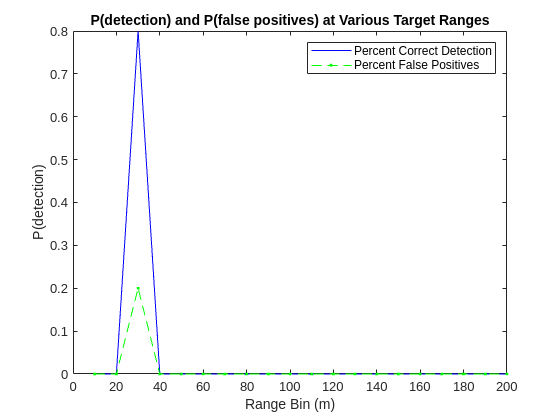

histogram_vals = zeros(MAX_BIN,3);

for bin_num = 1:MAX_BIN
    histogram_vals(bin_num, 1) = bin_num;
    count = 0;
    detected = 0;
    false_pos = 0;
    for frame = 1: TOTAL_FRAMES
        if (bin_classification(frame) == bin_num)
            count = count + 1;
            if table_graph_data{frame, 3}
                detected = detected + 1;
            end
            if table_graph_data{frame, 8}
                false_pos = false_pos + 1;
            end
        end
    end
    if (count ~= 0)
        histogram_vals(bin_num, 2) = detected/count;
        histogram_vals(bin_num, 3) = false_pos/count;
    end
end

figure
plot(histogram_vals(:,1)*10, histogram_vals(:,2), 'b');
hold on
plot(histogram_vals(:,1)*10, histogram_vals(:,3), '--.g');
hold off
ylabel("P(detection)")
xlabel("Range Bin (m)")
legend("Percent Correct Detection", "Percent False Positives")
title("P(detection) and P(false positives) at Various Target Ranges")
saveas(gcf, "histogram_plot.png")

Plot Error vs. Range

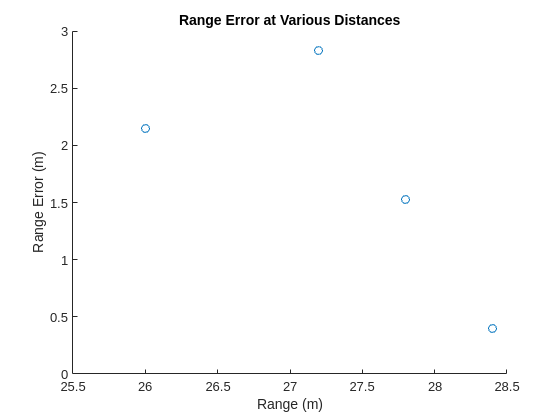

%% Error vs Range
range_error_plot = zeros(0,0);
for frame = 1: TOTAL_FRAMES
    val = table_graph_data{frame, 3};
    if (val(1) ~= 0)
        range_error_plot = [range_error_plot; [table_graph_data{frame, 1}, table_graph_data{frame, 5}]];
    end
end
figure

    scatter(range_error_plot(:,1), range_error_plot(:,2));

ylabel("Range Error (m)")
xlabel("Range (m)")
title("Range Error at Various Distances")
saveas(gcf, "error_plot.png")